ans = 'C:\Users\Ansh Singal\Desktop\study\ML\machine-learning-ex2\ex2'

load ex2data1.txt
a=ex2data1

a =    34.6237   78.0247         0
   30.2867   43.8950         0
   35.8474   72.9022         0
   60.1826   86.3086    1.0000
   79.0327   75.3444    1.0000
   45.0833   56.3164         0
   61.1067   96.5114    1.0000
   75.0247   46.5540    1.0000
   76.0988   87.4206    1.0000
   84.4328   43.5334    1.0000


pos = find(a(:,3)==1)

pos =      4
     5
     7
     8
     9
    10
    13
    14
    16
    17


neg = find(a(:,3)==0)

neg =      1
     2
     3
     6
    11
    12
    15
    18
    21
    23


xx=a(:,1)

xx =    34.6237
   30.2867
   35.8474
   60.1826
   79.0327
   45.0833
   61.1067
   75.0247
   76.0988
   84.4328


yy=a(:,2)

yy =    78.0247
   43.8950
   72.9022
   86.3086
   75.3444
   56.3164
   96.5114
   46.5540
   87.4206
   43.5334


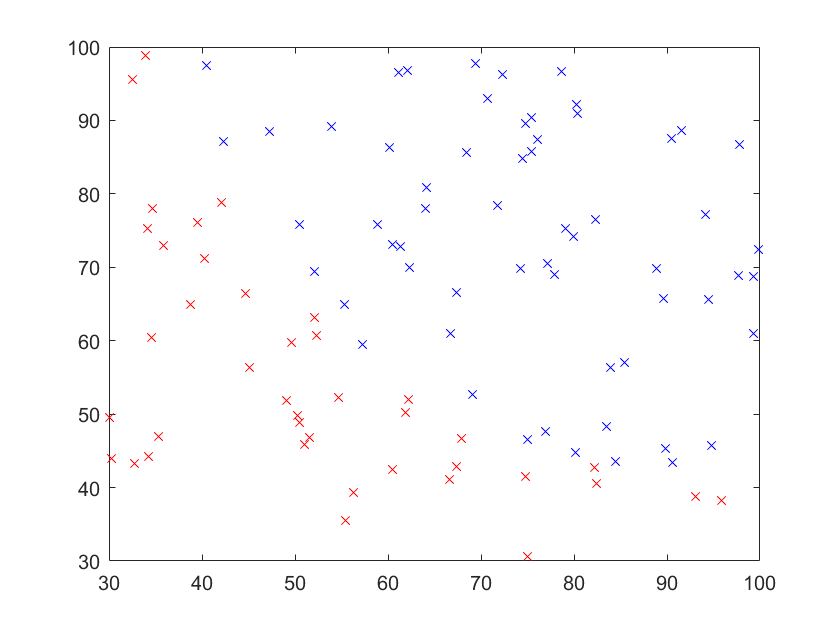

plot(xx(pos), yy(pos), 'bx')
hold on
plot(xx(neg), yy(neg), 'rx')
hold off

ab = [1 2 3 5 6 7 8 9 10]

ab =      1     2     3     5     6     7     8     9    10


sigmoid(ab)

ans =     0.7311    0.8808    0.9526    0.9933    0.9975    0.9991    0.9997    0.9999    1.0000


Explanation of the cost (binary crossentropy) function

Suppose the hypothesis function H(theta)(x)=(some)aa

this hypothesis is basically Sigmoid((Theta)(transposed)*X)

aa = linspace(0, 1, 10)

aa =          0    0.1111    0.2222    0.3333    0.4444    0.5556    0.6667    0.7778    0.8889    1.0000


bb = [1,1,1,1,1,1,1,1,1,1]

bb =      1     1     1     1     1     1     1     1     1     1


aaa=.99999999

aaa = 1.0000

bbb=1

bbb = 1

binary_crossentropy(aaa, bbb)

ans = 1.0000e-08

%here, 
one = ones(100,1)

one =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


y = a(:, 3)

y =      0
     0
     0
     1
     1
     0
     1
     1
     1
     1


x = [one a(:, [1,2])]

x =     1.0000   34.6237   78.0247
    1.0000   30.2867   43.8950
    1.0000   35.8474   72.9022
    1.0000   60.1826   86.3086
    1.0000   79.0327   75.3444
    1.0000   45.0833   56.3164
    1.0000   61.1067   96.5114
    1.0000   75.0247   46.5540
    1.0000   76.0988   87.4206
    1.0000   84.4328   43.5334


features = 3;
iterations = 100;
alpha = .001;

now, we apply gradient descent

%some problem here, the ans is the one given in fminunc

%theta = [1; 1; 1]
%temp = [1; 1; 1]
theta = zeros(features, 1)

theta =      0
     0
     0


temp = zeros(features, 1)

temp =      0
     0
     0


j = zeros(iterations, 1)

j =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


for i = 1:iterations
    hypothesis = sigmoid(x*theta)
    for l = 1:features
        temp(l) = theta(l) - alpha*sum((hypothesis-y).*x(:,l))/(length(y));
    end
    theta = temp
    j(i)=sum(binary_crossentropy(hypothesis, y))
end

hypothesis =     0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000


theta =     0.0001
    0.0120
    0.0113


j =     0.6931
         0
         0
         0
         0
         0
         0
         0
         0
         0


hypothesis =     0.7849
    0.7023
    0.7776
    0.8449
    0.8579
    0.7642
    0.8607
    0.8062
    0.8697
    0.8182


theta =    -0.0001
    0.0025
    0.0009


j =     0.6931
    0.6983
         0
         0
         0
         0
         0
         0
         0
         0


hypothesis =     0.5390
    0.5286
    0.5386
    0.5565
    0.5656
    0.5405
    0.5594
    0.5567
    0.5665
    0.5618


theta =    -0.0001
    0.0106
    0.0084


j =     0.6931
    0.6983
    0.6597
         0
         0
         0
         0
         0
         0
         0


hypothesis =     0.7361
    0.6664
    0.7302
    0.7969
    0.8138
    0.7219
    0.8120
    0.7667
    0.8243
    0.7798


theta =    -0.0002
    0.0039
    0.0010


j =     0.6931
    0.6983
    0.6597
    0.6616
         0
         0
         0
         0
         0
         0


hypothesis =     0.5527
    0.5401
    0.5526
    0.5791
    0.5942
    0.5574
    0.5824
    0.5835
    0.5943
    0.5917


theta =    -0.0002
    0.0103
    0.0069


j =     0.6931
    0.6983
    0.6597
    0.6616
    0.6489
         0
         0
         0
         0
         0


hypothesis =     0.7106
    0.6495
    0.7058
    0.7720
    0.7923
    0.7018
    0.7858
    0.7499
    0.8009
    0.7639


theta =    -0.0004
    0.0049
    0.0009


j =     0.6931
    0.6983
    0.6597
    0.6616
    0.6489
    0.6497
         0
         0
         0
         0


hypothesis =     0.5601
    0.5471
    0.5604
    0.5927
    0.6126
    0.5679
    0.5960
    0.6016
    0.6117
    0.6120


theta =    -0.0004
    0.0103
    0.0058


j =     0.6931
    0.6983
    0.6597
    0.6616
    0.6489
    0.6497
    0.6431
         0
         0
         0


hypothesis =     0.6926
    0.6383
    0.6889
    0.7547
    0.7779
    0.6884
    0.7672
    0.7396
    0.7848
    0.7545


theta =    -0.0005
    0.0058
    0.0008


j =     0.6931
    0.6983
    0.6597
    0.6616
    0.6489
    0.6497
    0.6431
    0.6435
         0
         0


hypothesis =     0.5649
    0.5520
    0.5656
    0.6023
    0.6259
    0.5754
    0.6055
    0.6151
    0.6242
    0.6273


theta =    -0.0005
    0.0103
    0.0050


j =     0.6931
    0.6983
    0.6597
    0.6616
    0.6489
    0.6497
    0.6431
    0.6435
    0.6395
         0


hypothesis =     0.6787
    0.6299
    0.6758
    0.7413
    0.7672
    0.6785
    0.7528
    0.7324
    0.7726
    0.7482


theta =    -0.0007
    0.0064
    0.0007


j =     0.6931
    0.6983
    0.6597
    0.6616
    0.6489
    0.6497
    0.6431
    0.6435
    0.6395
    0.6396


hypothesis =     0.5684
    0.5558
    0.5695
    0.6096
    0.6364
    0.5813
    0.6127
    0.6258
    0.6339
    0.6394


theta =    -0.0007
    0.0104
    0.0043


j =     0.6931
    0.6983
    0.6597
    0.6616
    0.6489
    0.6497
    0.6431
    0.6435
    0.6395
    0.6396


hypothesis =     0.6675
    0.6234
    0.6653
    0.7306
    0.7587
    0.6707
    0.7411
    0.7270
    0.7627
    0.7435


theta =    -0.0008
    0.0070
    0.0006


j =     0.6931
    0.6983
    0.6597
    0.6616
    0.6489
    0.6497
    0.6431
    0.6435
    0.6395
    0.6396


hypothesis =     0.5712
    0.5589
    0.5726
    0.6156
    0.6448
    0.5860
    0.6185
    0.6345
    0.6417
    0.6492


theta =    -0.0008
    0.0104
    0.0038


j =     0.6931
    0.6983
    0.6597
    0.6616
    0.6489
    0.6497
    0.6431
    0.6435
    0.6395
    0.6396


hypothesis =     0.6582
    0.6180
    0.6567
    0.7217
    0.7518
    0.6642
    0.7313
    0.7227
    0.7546
    0.7397


theta =    -0.0009
    0.0075
    0.0005


j =     0.6931
    0.6983
    0.6597
    0.6616
    0.6489
    0.6497
    0.6431
    0.6435
    0.6395
    0.6396


hypothesis =     0.5736
    0.5615
    0.5752
    0.6205
    0.6519
    0.5900
    0.6233
    0.6418
    0.6483
    0.6575


theta =    -0.0010
    0.0105
    0.0033


j =     0.6931
    0.6983
    0.6597
    0.6616
    0.6489
    0.6497
    0.6431
    0.6435
    0.6395
    0.6396


hypothesis =     0.6503
    0.6135
    0.6494
    0.7142
    0.7460
    0.6589
    0.7230
    0.7191
    0.7477
    0.7366


theta =    -0.0011
    0.0079
    0.0004


j =     0.6931
    0.6983
    0.6597
    0.6616
    0.6489
    0.6497
    0.6431
    0.6435
    0.6395
    0.6396


hypothesis =     0.5757
    0.5637
    0.5775
    0.6248
    0.6579
    0.5934
    0.6275
    0.6480
    0.6538
    0.6644


theta =    -0.0011
    0.0105
    0.0029


j =     0.6931
    0.6983
    0.6597
    0.6616
    0.6489
    0.6497
    0.6431
    0.6435
    0.6395
    0.6396


hypothesis =     0.6436
    0.6097
    0.6432
    0.7078
    0.7410
    0.6543
    0.7159
    0.7160
    0.7418
    0.7340


theta =    -0.0012
    0.0082
    0.0004


j =     0.6931
    0.6983
    0.6597
    0.6616
    0.6489
    0.6497
    0.6431
    0.6435
    0.6395
    0.6396


hypothesis =     0.5775
    0.5657
    0.5795
    0.6285
    0.6630
    0.5964
    0.6312
    0.6532
    0.6586
    0.6703


theta =    -0.0012
    0.0106
    0.0026


j =     0.6931
    0.6983
    0.6597
    0.6616
    0.6489
    0.6497
    0.6431
    0.6435
    0.6395
    0.6396


hypothesis =     0.6379
    0.6064
    0.6378
    0.7022
    0.7367
    0.6504
    0.7097
    0.7134
    0.7367
    0.7317


theta =    -0.0013
    0.0085
    0.0003


j =     0.6931
    0.6983
    0.6597
    0.6616
    0.6489
    0.6497
    0.6431
    0.6435
    0.6395
    0.6396


hypothesis =     0.5792
    0.5674
    0.5813
    0.6318
    0.6675
    0.5990
    0.6344
    0.6578
    0.6629
    0.6754


theta =    -0.0014
    0.0106
    0.0023


j =     0.6931
    0.6983
    0.6597
    0.6616
    0.6489
    0.6497
    0.6431
    0.6435
    0.6395
    0.6396


hypothesis =     0.6330
    0.6036
    0.6332
    0.6974
    0.7329
    0.6470
    0.7043
    0.7111
    0.7322
    0.7297


theta =    -0.0015
    0.0088
    0.0003


j =     0.6931
    0.6983
    0.6597
    0.6616
    0.6489
    0.6497
    0.6431
    0.6435
    0.6395
    0.6396


hypothesis =     0.5808
    0.5689
    0.5830
    0.6348
    0.6714
    0.6014
    0.6374
    0.6617
    0.6666
    0.6797


theta =    -0.0015
    0.0106
    0.0021


j =     0.6931
    0.6983
    0.6597
    0.6616
    0.6489
    0.6497
    0.6431
    0.6435
    0.6395
    0.6396


hypothesis =     0.6287
    0.6011
    0.6292
    0.6931
    0.7295
    0.6440
    0.6997
    0.7090
    0.7283
    0.7279


theta =    -0.0016
    0.0090
    0.0003


j =     0.6931
    0.6983
    0.6597
    0.6616
    0.6489
    0.6497
    0.6431
    0.6435
    0.6395
    0.6396


hypothesis =     0.5822
    0.5703
    0.5845
    0.6374
    0.6749
    0.6034
    0.6400
    0.6651
    0.6698
    0.6835


theta =    -0.0017
    0.0106
    0.0018


j =     0.6931
    0.6983
    0.6597
    0.6616
    0.6489
    0.6497
    0.6431
    0.6435
    0.6395
    0.6396


hypothesis =     0.6249
    0.5990
    0.6258
    0.6894
    0.7266
    0.6414
    0.6955
    0.7072
    0.7248
    0.7263


theta =    -0.0018
    0.0092
    0.0003


j =     0.6931
    0.6983
    0.6597
    0.6616
    0.6489
    0.6497
    0.6431
    0.6435
    0.6395
    0.6396


hypothesis =     0.5836
    0.5716
    0.5859
    0.6397
    0.6779
    0.6053
    0.6423
    0.6681
    0.6727
    0.6868


theta =    -0.0018
    0.0106
    0.0017


j =     0.6931
    0.6983
    0.6597
    0.6616
    0.6489
    0.6497
    0.6431
    0.6435
    0.6395
    0.6396


hypothesis =     0.6217
    0.5971
    0.6227
    0.6862
    0.7240
    0.6391
    0.6919
    0.7055
    0.7218
    0.7248


theta =    -0.0019
    0.0093
    0.0003


j =     0.6931
    0.6983
    0.6597
    0.6616
    0.6489
    0.6497
    0.6431
    0.6435
    0.6395
    0.6396


hypothesis =     0.5848
    0.5727
    0.5872
    0.6419
    0.6806
    0.6069
    0.6445
    0.6707
    0.6753
    0.6897


theta =    -0.0019
    0.0106
    0.0015


j =     0.6931
    0.6983
    0.6597
    0.6616
    0.6489
    0.6497
    0.6431
    0.6435
    0.6395
    0.6396


hypothesis =     0.6188
    0.5955
    0.6201
    0.6833
    0.7217
    0.6371
    0.6887
    0.7040
    0.7191
    0.7235


theta =    -0.0020
    0.0095
    0.0003


j =     0.6931
    0.6983
    0.6597
    0.6616
    0.6489
    0.6497
    0.6431
    0.6435
    0.6395
    0.6396


hypothesis =     0.5859
    0.5737
    0.5884
    0.6438
    0.6830
    0.6084
    0.6464
    0.6730
    0.6776
    0.6922


theta =    -0.0021
    0.0106
    0.0014


j =     0.6931
    0.6983
    0.6597
    0.6616
    0.6489
    0.6497
    0.6431
    0.6435
    0.6395
    0.6396


hypothesis =     0.6163
    0.5940
    0.6177
    0.6808
    0.7196
    0.6353
    0.6859
    0.7027
    0.7167
    0.7223


theta =    -0.0022
    0.0096
    0.0003


j =     0.6931
    0.6983
    0.6597
    0.6616
    0.6489
    0.6497
    0.6431
    0.6435
    0.6395
    0.6396


hypothesis =     0.5870
    0.5746
    0.5895
    0.6455
    0.6851
    0.6097
    0.6481
    0.6750
    0.6797
    0.6944


theta =    -0.0022
    0.0106
    0.0013


j =     0.6931
    0.6983
    0.6597
    0.6616
    0.6489
    0.6497
    0.6431
    0.6435
    0.6395
    0.6396


hypothesis =     0.6141
    0.5928
    0.6157
    0.6785
    0.7178
    0.6338
    0.6835
    0.7015
    0.7145
    0.7212


theta =    -0.0023
    0.0097
    0.0003


j =     0.6931
    0.6983
    0.6597
    0.6616
    0.6489
    0.6497
    0.6431
    0.6435
    0.6395
    0.6396


hypothesis =     0.5880
    0.5754
    0.5905
    0.6470
    0.6870
    0.6109
    0.6497
    0.6768
    0.6815
    0.6963


theta =    -0.0024
    0.0106
    0.0012


j =     0.6931
    0.6983
    0.6597
    0.6616
    0.6489
    0.6497
    0.6431
    0.6435
    0.6395
    0.6396


hypothesis =     0.6122
    0.5916
    0.6139
    0.6765
    0.7161
    0.6324
    0.6813
    0.7004
    0.7126
    0.7202


theta =    -0.0025
    0.0098
    0.0003


j =     0.6931
    0.6983
    0.6597
    0.6616
    0.6489
    0.6497
    0.6431
    0.6435
    0.6395
    0.6396


hypothesis =     0.5889
    0.5761
    0.5914
    0.6484
    0.6887
    0.6120
    0.6512
    0.6784
    0.6832
    0.6980


theta =    -0.0025
    0.0106
    0.0011


j =     0.6931
    0.6983
    0.6597
    0.6616
    0.6489
    0.6497
    0.6431
    0.6435
    0.6395
    0.6396


hypothesis =     0.6105
    0.5906
    0.6123
    0.6748
    0.7147
    0.6311
    0.6793
    0.6994
    0.7110
    0.7193


theta =    -0.0026
    0.0099
    0.0003


j =     0.6931
    0.6983
    0.6597
    0.6616
    0.6489
    0.6497
    0.6431
    0.6435
    0.6395
    0.6396


hypothesis =     0.5897
    0.5768
    0.5922
    0.6497
    0.6901
    0.6129
    0.6524
    0.6798
    0.6847
    0.6995


theta =    -0.0026
    0.0106
    0.0010


j =     0.6931
    0.6983
    0.6597
    0.6616
    0.6489
    0.6497
    0.6431
    0.6435
    0.6395
    0.6396


hypothesis =     0.6090
    0.5897
    0.6109
    0.6732
    0.7133
    0.6300
    0.6776
    0.6985
    0.7095
    0.7185


theta =    -0.0027
    0.0100
    0.0003


j =     0.6931
    0.6983
    0.6597
    0.6616
    0.6489
    0.6497
    0.6431
    0.6435
    0.6395
    0.6396


hypothesis =     0.5904
    0.5774
    0.5930
    0.6508
    0.6915
    0.6138
    0.6536
    0.6810
    0.6860
    0.7008


theta =    -0.0028
    0.0106
    0.0009


j =     0.6931
    0.6983
    0.6597
    0.6616
    0.6489
    0.6497
    0.6431
    0.6435
    0.6395
    0.6396


hypothesis =     0.6077
    0.5889
    0.6097
    0.6718
    0.7122
    0.6291
    0.6761
    0.6977
    0.7081
    0.7177


theta =    -0.0029
    0.0100
    0.0003


j =     0.6931
    0.6983
    0.6597
    0.6616
    0.6489
    0.6497
    0.6431
    0.6435
    0.6395
    0.6396


hypothesis =     0.5911
    0.5779
    0.5937
    0.6518
    0.6926
    0.6145
    0.6547
    0.6821
    0.6872
    0.7019


theta =    -0.0029
    0.0106
    0.0009


j =     0.6931
    0.6983
    0.6597
    0.6616
    0.6489
    0.6497
    0.6431
    0.6435
    0.6395
    0.6396


hypothesis =     0.6066
    0.5882
    0.6086
    0.6706
    0.7111
    0.6282
    0.6747
    0.6970
    0.7069
    0.7171


theta =    -0.0030
    0.0101
    0.0003


j =     0.6931
    0.6983
    0.6597
    0.6616
    0.6489
    0.6497
    0.6431
    0.6435
    0.6395
    0.6396


hypothesis =     0.5917
    0.5784
    0.5943
    0.6528
    0.6937
    0.6152
    0.6556
    0.6830
    0.6882
    0.7030


theta =    -0.0031
    0.0106
    0.0008


j =     0.6931
    0.6983
    0.6597
    0.6616
    0.6489
    0.6497
    0.6431
    0.6435
    0.6395
    0.6396


hypothesis =     0.6055
    0.5876
    0.6076
    0.6695
    0.7102
    0.6274
    0.6736
    0.6963
    0.7059
    0.7165


theta =    -0.0031
    0.0101
    0.0003


j =     0.6931
    0.6983
    0.6597
    0.6616
    0.6489
    0.6497
    0.6431
    0.6435
    0.6395
    0.6396


hypothesis =     0.5923
    0.5789
    0.5949
    0.6536
    0.6946
    0.6159
    0.6565
    0.6839
    0.6892
    0.7039


theta =    -0.0032
    0.0106
    0.0008


j =     0.6931
    0.6983
    0.6597
    0.6616
    0.6489
    0.6497
    0.6431
    0.6435
    0.6395
    0.6396


hypothesis =     0.6046
    0.5871
    0.6067
    0.6685
    0.7094
    0.6267
    0.6725
    0.6957
    0.7049
    0.7159


theta =    -0.0033
    0.0102
    0.0003


j =     0.6931
    0.6983
    0.6597
    0.6616
    0.6489
    0.6497
    0.6431
    0.6435
    0.6395
    0.6396


hypothesis =     0.5928
    0.5792
    0.5954
    0.6543
    0.6955
    0.6164
    0.6573
    0.6846
    0.6900
    0.7047


theta =    -0.0033
    0.0106
    0.0008


j =     0.6931
    0.6983
    0.6597
    0.6616
    0.6489
    0.6497
    0.6431
    0.6435
    0.6395
    0.6396


hypothesis =     0.6038
    0.5866
    0.6060
    0.6677
    0.7086
    0.6261
    0.6716
    0.6952
    0.7041
    0.7154


theta =    -0.0034
    0.0102
    0.0004


j =     0.6931
    0.6983
    0.6597
    0.6616
    0.6489
    0.6497
    0.6431
    0.6435
    0.6395
    0.6396


hypothesis =     0.5933
    0.5796
    0.5959
    0.6550
    0.6962
    0.6169
    0.6580
    0.6853
    0.6908
    0.7054


theta =    -0.0035
    0.0106
    0.0007


j =     0.6931
    0.6983
    0.6597
    0.6616
    0.6489
    0.6497
    0.6431
    0.6435
    0.6395
    0.6396


hypothesis =     0.6031
    0.5861
    0.6053
    0.6669
    0.7079
    0.6256
    0.6707
    0.6947
    0.7033
    0.7149


theta =    -0.0036
    0.0102
    0.0004


j =     0.6931
    0.6983
    0.6597
    0.6616
    0.6489
    0.6497
    0.6431
    0.6435
    0.6395
    0.6396


hypothesis =     0.5937
    0.5799
    0.5963
    0.6556
    0.6969
    0.6173
    0.6586
    0.6859
    0.6915
    0.7060


theta =    -0.0036
    0.0106
    0.0007


j =     0.6931
    0.6983
    0.6597
    0.6616
    0.6489
    0.6497
    0.6431
    0.6435
    0.6395
    0.6396


hypothesis =     0.6025
    0.5857
    0.6047
    0.6663
    0.7074
    0.6251
    0.6700
    0.6943
    0.7027
    0.7145


theta =    -0.0037
    0.0103
    0.0004


j =     0.6931
    0.6983
    0.6597
    0.6616
    0.6489
    0.6497
    0.6431
    0.6435
    0.6395
    0.6396


hypothesis =     0.5941
    0.5802
    0.5967
    0.6561
    0.6975
    0.6177
    0.6592
    0.6864
    0.6921
    0.7065


theta =    -0.0038
    0.0105
    0.0007


j =     0.6931
    0.6983
    0.6597
    0.6616
    0.6489
    0.6497
    0.6431
    0.6435
    0.6395
    0.6396


hypothesis =     0.6019
    0.5854
    0.6042
    0.6657
    0.7068
    0.6246
    0.6693
    0.6939
    0.7021
    0.7141


theta =    -0.0038
    0.0103
    0.0004


j =     0.6931
    0.6983
    0.6597
    0.6616
    0.6489
    0.6497
    0.6431
    0.6435
    0.6395
    0.6396


hypothesis =     0.5945
    0.5804
    0.5970
    0.6566
    0.6980
    0.6181
    0.6597
    0.6868
    0.6926
    0.7070


theta =    -0.0039
    0.0105
    0.0006


j =     0.6931
    0.6983
    0.6597
    0.6616
    0.6489
    0.6497
    0.6431
    0.6435
    0.6395
    0.6396


hypothesis =     0.6014
    0.5851
    0.6037
    0.6651
    0.7063
    0.6243
    0.6687
    0.6936
    0.7015
    0.7138


theta =    -0.0040
    0.0103
    0.0004


j =     0.6931
    0.6983
    0.6597
    0.6616
    0.6489
    0.6497
    0.6431
    0.6435
    0.6395
    0.6396


hypothesis =     0.5948
    0.5807
    0.5973
    0.6571
    0.6985
    0.6184
    0.6601
    0.6872
    0.6931
    0.7074


theta =    -0.0040
    0.0105
    0.0006


j =     0.6931
    0.6983
    0.6597
    0.6616
    0.6489
    0.6497
    0.6431
    0.6435
    0.6395
    0.6396


hypothesis =     0.6010
    0.5848
    0.6033
    0.6646
    0.7059
    0.6239
    0.6682
    0.6932
    0.7011
    0.7135


theta =    -0.0041
    0.0103
    0.0004


j =     0.6931
    0.6983
    0.6597
    0.6616
    0.6489
    0.6497
    0.6431
    0.6435
    0.6395
    0.6396


hypothesis =     0.5951
    0.5808
    0.5976
    0.6575
    0.6989
    0.6187
    0.6605
    0.6876
    0.6935
    0.7078


theta =    -0.0042
    0.0105
    0.0006


j =     0.6931
    0.6983
    0.6597
    0.6616
    0.6489
    0.6497
    0.6431
    0.6435
    0.6395
    0.6396


hypothesis =     0.6006
    0.5846
    0.6030
    0.6642
    0.7055
    0.6236
    0.6678
    0.6930
    0.7006
    0.7132


theta =    -0.0043
    0.0103
    0.0004


j =     0.6931
    0.6983
    0.6597
    0.6616
    0.6489
    0.6497
    0.6431
    0.6435
    0.6395
    0.6396


hypothesis =     0.5953
    0.5810
    0.5978
    0.6578
    0.6993
    0.6189
    0.6609
    0.6879
    0.6939
    0.7082


theta =    -0.0043
    0.0105
    0.0006


j =     0.6931
    0.6983
    0.6597
    0.6616
    0.6489
    0.6497
    0.6431
    0.6435
    0.6395
    0.6396


hypothesis =     0.6003
    0.5843
    0.6026
    0.6638
    0.7052
    0.6233
    0.6674
    0.6927
    0.7003
    0.7130


theta =    -0.0044
    0.0104
    0.0004


j =     0.6931
    0.6983
    0.6597
    0.6616
    0.6489
    0.6497
    0.6431
    0.6435
    0.6395
    0.6396


hypothesis =     0.5955
    0.5812
    0.5981
    0.6581
    0.6996
    0.6192
    0.6612
    0.6882
    0.6943
    0.7085


theta =    -0.0045
    0.0105
    0.0006


j =     0.6931
    0.6983
    0.6597
    0.6616
    0.6489
    0.6497
    0.6431
    0.6435
    0.6395
    0.6396


hypothesis =     0.6000
    0.5841
    0.6023
    0.6635
    0.7049
    0.6231
    0.6670
    0.6925
    0.6999
    0.7128


theta =    -0.0045
    0.0104
    0.0004


j =     0.6931
    0.6983
    0.6597
    0.6616
    0.6489
    0.6497
    0.6431
    0.6435
    0.6395
    0.6396


hypothesis =     0.5957
    0.5813
    0.5983
    0.6584
    0.6999
    0.6194
    0.6615
    0.6885
    0.6946
    0.7087


theta =    -0.0046
    0.0105
    0.0006


j =     0.6931
    0.6983
    0.6597
    0.6616
    0.6489
    0.6497
    0.6431
    0.6435
    0.6395
    0.6396


hypothesis =     0.5997
    0.5839
    0.6021
    0.6632
    0.7046
    0.6229
    0.6667
    0.6923
    0.6996
    0.7126


theta =    -0.0047
    0.0104
    0.0004


j =     0.6931
    0.6983
    0.6597
    0.6616
    0.6489
    0.6497
    0.6431
    0.6435
    0.6395
    0.6396


hypothesis =     0.5959
    0.5814
    0.5984
    0.6587
    0.7002
    0.6195
    0.6618
    0.6887
    0.6949
    0.7090


theta =    -0.0047
    0.0105
    0.0006


j =     0.6931
    0.6983
    0.6597
    0.6616
    0.6489
    0.6497
    0.6431
    0.6435
    0.6395
    0.6396


hypothesis =     0.5995
    0.5838
    0.6019
    0.6630
    0.7044
    0.6227
    0.6664
    0.6921
    0.6994
    0.7124


theta =    -0.0048
    0.0104
    0.0004


j =     0.6931
    0.6983
    0.6597
    0.6616
    0.6489
    0.6497
    0.6431
    0.6435
    0.6395
    0.6396


hypothesis =     0.5961
    0.5815
    0.5986
    0.6589
    0.7004
    0.6197
    0.6621
    0.6889
    0.6951
    0.7092


theta =    -0.0049
    0.0105
    0.0006


j =     0.6931
    0.6983
    0.6597
    0.6616
    0.6489
    0.6497
    0.6431
    0.6435
    0.6395
    0.6396


hypothesis =     0.5993
    0.5836
    0.6017
    0.6627
    0.7042
    0.6225
    0.6662
    0.6919
    0.6991
    0.7122


theta =    -0.0050
    0.0104
    0.0004


j =     0.6931
    0.6983
    0.6597
    0.6616
    0.6489
    0.6497
    0.6431
    0.6435
    0.6395
    0.6396


hypothesis =     0.5962
    0.5816
    0.5988
    0.6591
    0.7006
    0.6198
    0.6623
    0.6891
    0.6953
    0.7094


theta =    -0.0050
    0.0105
    0.0006


j =     0.6931
    0.6983
    0.6597
    0.6616
    0.6489
    0.6497
    0.6431
    0.6435
    0.6395
    0.6396


hypothesis =     0.5991
    0.5835
    0.6015
    0.6625
    0.7040
    0.6223
    0.6659
    0.6918
    0.6989
    0.7121


theta =    -0.0051
    0.0104
    0.0005


j =     0.6931
    0.6983
    0.6597
    0.6616
    0.6489
    0.6497
    0.6431
    0.6435
    0.6395
    0.6396


hypothesis =     0.5964
    0.5817
    0.5989
    0.6593
    0.7008
    0.6200
    0.6625
    0.6892
    0.6955
    0.7095


theta =    -0.0052
    0.0105
    0.0005


j =     0.6931
    0.6983
    0.6597
    0.6616
    0.6489
    0.6497
    0.6431
    0.6435
    0.6395
    0.6396


hypothesis =     0.5989
    0.5834
    0.6013
    0.6623
    0.7038
    0.6222
    0.6657
    0.6916
    0.6988
    0.7120


theta =    -0.0052
    0.0104
    0.0005


j =     0.6931
    0.6983
    0.6597
    0.6616
    0.6489
    0.6497
    0.6431
    0.6435
    0.6395
    0.6396


hypothesis =     0.5965
    0.5818
    0.5990
    0.6594
    0.7010
    0.6201
    0.6626
    0.6894
    0.6957
    0.7097


theta =    -0.0053
    0.0105
    0.0005


j =     0.6931
    0.6983
    0.6597
    0.6616
    0.6489
    0.6497
    0.6431
    0.6435
    0.6395
    0.6396


hypothesis =     0.5987
    0.5833
    0.6012
    0.6622
    0.7037
    0.6221
    0.6656
    0.6915
    0.6986
    0.7118


theta =    -0.0054
    0.0104
    0.0005


j =     0.6931
    0.6983
    0.6597
    0.6616
    0.6489
    0.6497
    0.6431
    0.6435
    0.6395
    0.6396


hypothesis =     0.5966
    0.5819
    0.5991
    0.6596
    0.7011
    0.6202
    0.6628
    0.6895
    0.6959
    0.7098


theta =    -0.0054
    0.0105
    0.0005


j =     0.6931
    0.6983
    0.6597
    0.6616
    0.6489
    0.6497
    0.6431
    0.6435
    0.6395
    0.6396


hypothesis =     0.5986
    0.5832
    0.6010
    0.6620
    0.7035
    0.6219
    0.6654
    0.6914
    0.6984
    0.7117


theta =    -0.0055
    0.0104
    0.0005


j =     0.6931
    0.6983
    0.6597
    0.6616
    0.6489
    0.6497
    0.6431
    0.6435
    0.6395
    0.6396


hypothesis =     0.5967
    0.5819
    0.5992
    0.6597
    0.7013
    0.6203
    0.6629
    0.6896
    0.6960
    0.7099


theta =    -0.0056
    0.0105
    0.0005


j =     0.6931
    0.6983
    0.6597
    0.6616
    0.6489
    0.6497
    0.6431
    0.6435
    0.6395
    0.6396


hypothesis =     0.5985
    0.5831
    0.6009
    0.6619
    0.7034
    0.6218
    0.6653
    0.6913
    0.6983
    0.7116


theta =    -0.0057
    0.0104
    0.0005


j =     0.6931
    0.6983
    0.6597
    0.6616
    0.6489
    0.6497
    0.6431
    0.6435
    0.6395
    0.6396


hypothesis =     0.5968
    0.5820
    0.5993
    0.6598
    0.7014
    0.6203
    0.6631
    0.6897
    0.6962
    0.7100


theta =    -0.0057
    0.0105
    0.0005


j =     0.6931
    0.6983
    0.6597
    0.6616
    0.6489
    0.6497
    0.6431
    0.6435
    0.6395
    0.6396


hypothesis =     0.5984
    0.5830
    0.6008
    0.6618
    0.7033
    0.6217
    0.6651
    0.6912
    0.6982
    0.7115


theta =    -0.0058
    0.0104
    0.0005


j =     0.6931
    0.6983
    0.6597
    0.6616
    0.6489
    0.6497
    0.6431
    0.6435
    0.6395
    0.6396


hypothesis =     0.5969
    0.5820
    0.5994
    0.6599
    0.7015
    0.6204
    0.6632
    0.6898
    0.6963
    0.7101


theta =    -0.0059
    0.0105
    0.0005


j =     0.6931
    0.6983
    0.6597
    0.6616
    0.6489
    0.6497
    0.6431
    0.6435
    0.6395
    0.6396


hypothesis =     0.5983
    0.5829
    0.6007
    0.6617
    0.7032
    0.6217
    0.6650
    0.6911
    0.6981
    0.7115


theta =    -0.0059
    0.0104
    0.0005


j =     0.6931
    0.6983
    0.6597
    0.6616
    0.6489
    0.6497
    0.6431
    0.6435
    0.6395
    0.6396


hypothesis =     0.5969
    0.5820
    0.5994
    0.6600
    0.7016
    0.6205
    0.6633
    0.6899
    0.6964
    0.7102


theta =    -0.0060
    0.0105
    0.0005


j =     0.6931
    0.6983
    0.6597
    0.6616
    0.6489
    0.6497
    0.6431
    0.6435
    0.6395
    0.6396


hypothesis =     0.5982
    0.5829
    0.6006
    0.6616
    0.7031
    0.6216
    0.6649
    0.6911
    0.6980
    0.7114


theta =    -0.0061
    0.0104
    0.0005


j =     0.6931
    0.6983
    0.6597
    0.6616
    0.6489
    0.6497
    0.6431
    0.6435
    0.6395
    0.6396


hypothesis =     0.5970
    0.5821
    0.5995
    0.6601
    0.7017
    0.6205
    0.6634
    0.6899
    0.6965
    0.7102


theta =    -0.0061
    0.0105
    0.0005


j =     0.6931
    0.6983
    0.6597
    0.6616
    0.6489
    0.6497
    0.6431
    0.6435
    0.6395
    0.6396


hypothesis =     0.5981
    0.5828
    0.6006
    0.6615
    0.7031
    0.6215
    0.6649
    0.6910
    0.6979
    0.7113


theta =    -0.0062
    0.0104
    0.0005


j =     0.6931
    0.6983
    0.6597
    0.6616
    0.6489
    0.6497
    0.6431
    0.6435
    0.6395
    0.6396


hypothesis =     0.5970
    0.5821
    0.5995
    0.6602
    0.7018
    0.6206
    0.6635
    0.6900
    0.6966
    0.7103


theta =    -0.0063
    0.0105
    0.0005


j =     0.6931
    0.6983
    0.6597
    0.6616
    0.6489
    0.6497
    0.6431
    0.6435
    0.6395
    0.6396


hypothesis =     0.5981
    0.5828
    0.6005
    0.6614
    0.7030
    0.6215
    0.6648
    0.6909
    0.6979
    0.7113


theta =    -0.0064
    0.0105
    0.0005


j =     0.6931
    0.6983
    0.6597
    0.6616
    0.6489
    0.6497
    0.6431
    0.6435
    0.6395
    0.6396


hypothesis =     0.5971
    0.5821
    0.5996
    0.6603
    0.7019
    0.6206
    0.6635
    0.6900
    0.6966
    0.7104


theta =    -0.0064
    0.0105
    0.0005


j =     0.6931
    0.6983
    0.6597
    0.6616
    0.6489
    0.6497
    0.6431
    0.6435
    0.6395
    0.6396


hypothesis =     0.5980
    0.5827
    0.6004
    0.6614
    0.7029
    0.6214
    0.6647
    0.6909
    0.6978
    0.7112


theta =    -0.0065
    0.0105
    0.0005


j =     0.6931
    0.6983
    0.6597
    0.6616
    0.6489
    0.6497
    0.6431
    0.6435
    0.6395
    0.6396


hypothesis =     0.5971
    0.5821
    0.5996
    0.6603
    0.7019
    0.6206
    0.6636
    0.6901
    0.6967
    0.7104


theta =    -0.0066
    0.0105
    0.0005


j =     0.6931
    0.6983
    0.6597
    0.6616
    0.6489
    0.6497
    0.6431
    0.6435
    0.6395
    0.6396


hypothesis =     0.5979
    0.5827
    0.6004
    0.6613
    0.7029
    0.6213
    0.6647
    0.6909
    0.6977
    0.7112


theta =    -0.0066
    0.0105
    0.0005


j =     0.6931
    0.6983
    0.6597
    0.6616
    0.6489
    0.6497
    0.6431
    0.6435
    0.6395
    0.6396


hypothesis =     0.5972
    0.5821
    0.5996
    0.6604
    0.7020
    0.6207
    0.6637
    0.6901
    0.6968
    0.7105


theta =    -0.0067
    0.0105
    0.0005


j =     0.6931
    0.6983
    0.6597
    0.6616
    0.6489
    0.6497
    0.6431
    0.6435
    0.6395
    0.6396


hypothesis =     0.5979
    0.5826
    0.6003
    0.6613
    0.7028
    0.6213
    0.6646
    0.6908
    0.6977
    0.7111


theta =    -0.0068
    0.0105
    0.0005


j =     0.6931
    0.6983
    0.6597
    0.6616
    0.6489
    0.6497
    0.6431
    0.6435
    0.6395
    0.6396


hypothesis =     0.5972
    0.5822
    0.5997
    0.6604
    0.7020
    0.6207
    0.6637
    0.6902
    0.6968
    0.7105


theta =    -0.0068
    0.0105
    0.0005


j =     0.6931
    0.6983
    0.6597
    0.6616
    0.6489
    0.6497
    0.6431
    0.6435
    0.6395
    0.6396


hypothesis =     0.5978
    0.5826
    0.6003
    0.6612
    0.7028
    0.6213
    0.6646
    0.6908
    0.6976
    0.7111


theta =    -0.0069
    0.0105
    0.0005


j =     0.6931
    0.6983
    0.6597
    0.6616
    0.6489
    0.6497
    0.6431
    0.6435
    0.6395
    0.6396


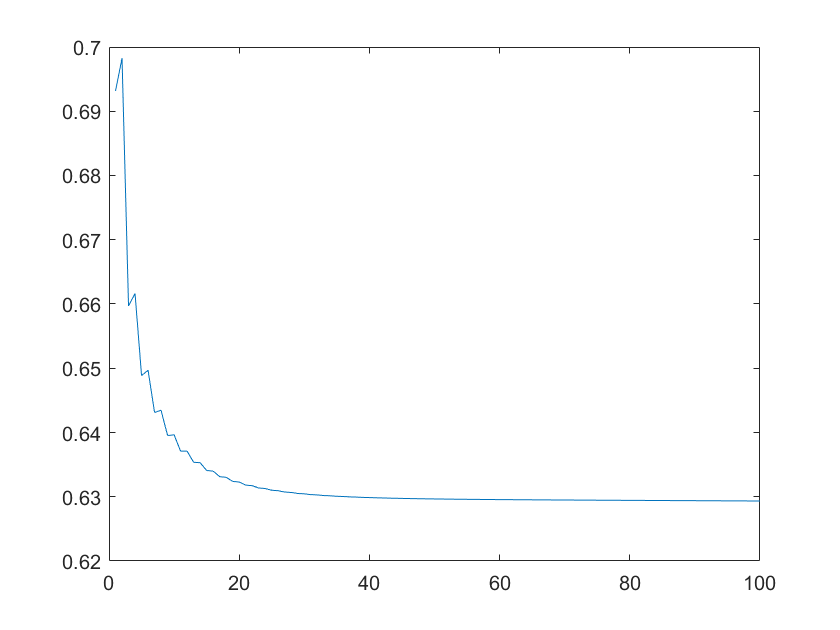

plot(j)

theta

theta =    -0.0069
    0.0105
    0.0005


%plotDecisionBoundary(theta, x, y)

%this one is correct
% using fminunc now
options = optimset('GradObj', 'on', 'MaxIter', 400);
initial_theta = [0;0;0];
[theta, cost] = fminunc(@(t)(costFunction(t, x, y)), initial_theta, options);

grad =    -0.1000
  -12.0092
  -11.2628


grad =     0.4000
   20.8129
   21.8482


grad =     0.4000
   20.8129
   21.8482


grad =     0.3757
   19.4850
   20.4520


grad =     0.0799
    0.2760
    1.0541


grad =     0.0712
   -0.2986
    0.4482


grad =     0.0671
   -0.5505
    0.1437


grad =     0.0613
   -0.8535
   -0.3370


grad =     0.0594
   -0.8391
   -0.5966


grad =     0.0636
   -0.4306
   -0.4168


grad =     0.0684
   -0.0797
   -0.1143


grad =     0.0698
    0.0119
   -0.0090


grad =     0.0703
    0.0352
    0.0231


grad =     0.0712
    0.0873
    0.0975


grad =     0.0725
    0.1583
    0.1997


grad =     0.0747
    0.2798
    0.3749


grad =     0.0781
    0.4708
    0.6501


grad =     0.0836
    0.7790
    1.0945


grad =     0.0921
    1.2650
    1.7954


grad =     0.1049
    2.0159
    2.8796


grad =     0.1229
    3.1076
    4.4621


grad =     0.1438
    4.4753
    6.4797


grad =     0.1565
    5.5891
    8.2727


grad =     0.1433
    5.5020
    8.5397


grad =     0.1110
    4.5069
    7.1859


grad =     0.0753
    3.3358
    5.0410


grad =     0.0426
    2.1096
    2.8361


grad =     0.0223
    1.2304
    1.4509


grad =     0.0106
    0.6568
    0.6686


grad =     0.0051
    0.3497
    0.3190


grad =     0.0025
    0.1837
    0.1676


grad =     0.0004
    0.0315
    0.0523


grad =    -0.0004
   -0.0418
    0.0076


grad =    -0.0004
   -0.0464
    0.0056


grad =    -0.0000
   -0.0179
    0.0123


grad =     0.0001
    0.0009
    0.0086


grad =     0.0000
    0.0019
    0.0024


grad = 	1.0e+-3 *

    0.0057
    0.3852
    0.3048


grad = 	1.0e+-4 *

    0.0044
    0.3340
    0.2299


grad = 	1.0e+-5 *

    0.0015
    0.1203
    0.1050



Local minimum found.

Optimization completed because the size of the gradient is less than
the default value of the optimality tolerance.

<stopping criteria details>



theta

theta =   -25.1613
    0.2062
    0.2015


cost

cost = 0.2035

theta

theta =   -25.1613
    0.2062
    0.2015


plot(xx(pos), yy(pos), 'bx')
hold on
plot(xx(neg), yy(neg), 'rx')
syms p q
p = 30:100

p =     30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50    51    52    53    54    55    56    57    58    59    60    61    62    63    64    65    66    67    68    69    70    71    72    73    74    75    76    77    78    79


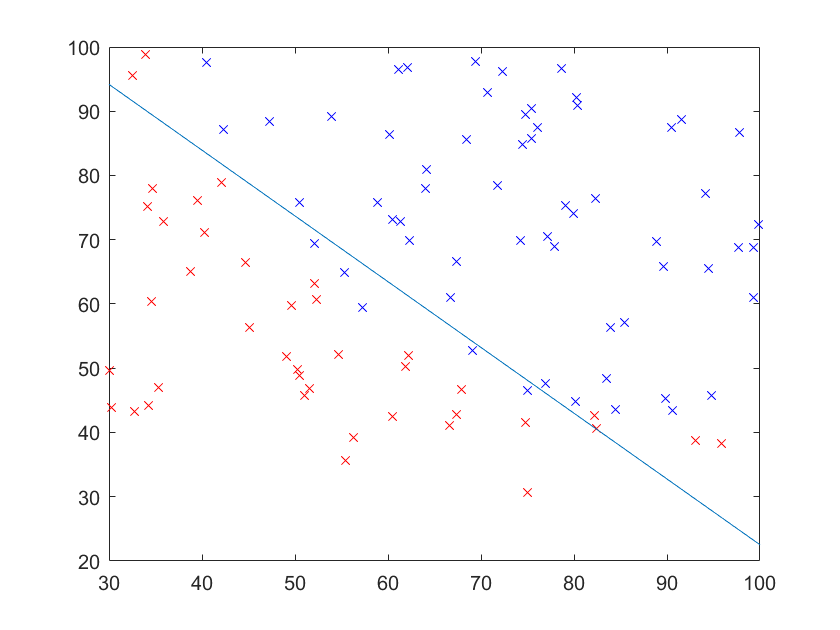

q = (-1/theta(3))*(theta(2)*p + theta(1));
plot(p, q)
hold off

function[sig] = sigmoid(x)
    sig = 1./(1+exp(-x));
end

%parameters for binary crossentropy loss:%data:activation funct applied
                                         %y: actual output
function[j] = binary_crossentropy(data, y)
    j = sum(-y.*log(data)-(1.-y).*log(1.-data))/length(y);
end




%cost function for fminunc
function [J, grad] = costFunction(theta, x, y)
%COSTFUNCTION Compute cost and gradient for logistic regression
%   J = COSTFUNCTION(theta, X, y) computes the cost of using theta as the
%   parameter for logistic regression and the gradient of the cost
%   w.r.t. to the parameters
m = length(y); 
J = 0;
grad = zeros(size(theta));

% ====================== YOUR CODE HERE ======================
% Instructions: Compute the cost of a particular choice of theta.
%               You should set J to the cost.
%               Compute the partial derivatives and set grad to the partial
%               derivatives of the cost w.r.t. each parameter in theta
hypothesis = sigmoid(x*theta);
grad = (x'*(hypothesis-y)/m)
J = binary_crossentropy(hypothesis, y);
end

